# **GAIT RECOGNITION BY ML ANALYSIS ON IMU DATA**

clear ;
close all;
clc
addpath("include");

## **MACROS**

NCOLUMNS = 150;

STARTING_FS = 100;

activities = ["PhaseONE","PhaseTWO","PhaseTHREE", "PhaseFOUR"];

features_avaiable = [
                       "%s mean%s",...                  %01
                       "%s std%s",...                   %02
                       "%s peak%s",...                  %03
                       "%s peak position%s",...         %04
                       "%s mediana%s",...               %05
                       "%s variance%s",...              %06
                       "%s covariance%s",...            %07
                       "%s range%s",...                 %08
                       "%s rms%s",...                   %09
                       "%s mode%s",...                  %10
                       "%s mean or median abs dev%s",...    %11
                       %"%s meanFFT%s"
                       ];

## **DATA IMPORTING**

file1 = readtable("data/record_10-11-21_1st_random.csv", 'VariableNamingRule','preserve');
file2 = readtable("data/record_10-11-21_2nd_linAccZ.csv", 'VariableNamingRule','preserve');

## **CREATION OF THE DATA STRUCTURE**

dataset = {file1, file2};

data = Z_sortData(dataset);


ans =      1     2


## RAW DATA ANALYSIS

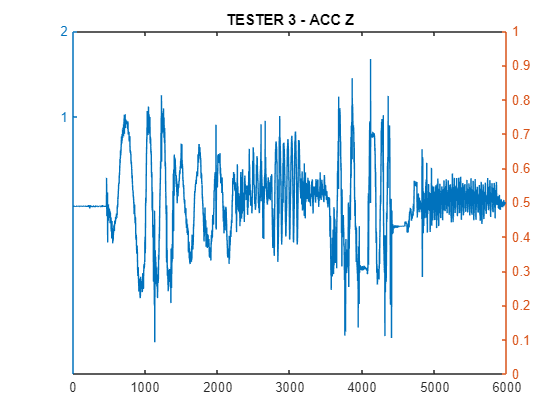

data_index  = 3;

figure, yyaxis left, plot(data(:,data_index))
yticks([1, 2, 3, 4, 5, 6])

## RAW DATA ANALYSIS COLORED BY ACTIVITY

sub_index   = 1;
data_index  = 1;

[acceleration, acc_id, time] = Get_acceleration(sub_index, data_index, subjects, fs);
Visualizzazione_accelerazioni(activities,acceleration,acc_id,time,getDirection(sub_index, data_index))

## HISTOGRAM ANALYSIS

%sub_index   = 1;
%data_index  = 1;
%[acceleration, acc_id, time] = Get_acceleration(sub_index, data_index, subjects, fs);

%a1 = 5;
%a2 = 2;
%getHistogram(acceleration,a1,a2, acc_id, activities)

## FREQUENCIES ANALYSIS

sub_index   = 1;
data_index  = 1;
[acceleration, acc_id, time] = Get_acceleration(sub_index, data_index, subjects, fs);


activity_fft = 2;

time_w = time(acc_id == activity_fft);
acceleration_w = acceleration(acc_id == activity_fft);
figure
Plot_FFT(acceleration_w, fs,1,0);
title("Acceleration FFT - " + getDirection(sub_index,data_index))

## FREQUENCIES COMPARISON

sub_index   = 1;
data_index  = 9;
[acceleration, acc_id, time] = Get_acceleration(sub_index, data_index, subjects, fs);

activity_one_fft = 1;
activity_two_fft = 5;


acceleration_w = acceleration(acc_id == activity_one_fft);
figure
Plot_FFT(acceleration_w, fs,1,0);
hold on


time_s = time(acc_id==activity_two_fft);
acceleration_s = acceleration(acc_id==activity_two_fft);
Plot_FFT(acceleration_s, fs,1,0);
title(getDirection(sub_index,data_index))
legend(activities(activity_one_fft),activities(activity_two_fft))
title("COMPARISON FFT - " + getDirection(sub_index,data_index))

## FREQUENCIES FILTERING

sub_index   = 1;
data_index  = 1;
[acceleration, acc_id, time] = Get_acceleration(sub_index, data_index, subjects, fs);

activity_ID = 5;
acceleration_w = acceleration(acc_id == activity_ID);

% fcutoff: taglio = 1:fN
fcutoff = 0.005;
ord = 3;
[B, A] = Filtro2(acceleration_w, fs, fcutoff, ord);
title(getDirection(sub_index,data_index))
legend(activities(activity_ID),sprintf(activities(activity_ID) + " filtered"))

sub_index   = 1;
data_index  = 8;
[acceleration, acc_id, time] = Get_acceleration(sub_index, data_index, subjects, fs);

Visualizzazione_accelerazioni(activities,filter(B,A,acceleration),acc_id,time,getDirection(sub_index, data_index))

## FREQUENCIES FILTERING - BANDPASS

sub_index   = 1;
data_index  = 3;
[acceleration, acc_id, time] = Get_acceleration(sub_index, data_index, subjects, fs);

activity_ID = 1;
acceleration_w = acceleration(acc_id == activity_ID);

%fcutoff: taglio = 1:fN
fcutoff_low  = 0.005;   %0.25Hz
fcutoff_high = 0.2;     %20 Hz
ord = 3;
[B, A] = Filtro3bandpass(acceleration_w, fs, fcutoff_low, fcutoff_high, ord);
title(getDirection(sub_index,data_index))
legend(activities(activity_ID),sprintf(activities(activity_ID) + " filtered"))

## **CREATION OF STAT_C STRUCTURE**

stat_c = convertToStat(dataset,NCOLUMNS,1);

## STAT_C GRAPHICAL ANALYSIS

comp = 1;
sampleACT = 3;
sampleROW = 120;
sample = stat_c{sampleACT}(sampleROW,:,comp);
plot(sample)
title(sprintf(activities(sampleACT) + " - " + getDirection(comp) + ": ROW " + sampleROW));

## MACHINE LEARNING ALGORITHM

stat = [
    true,... % mean                      %01
    true,... % std                       %02
    true,... % peak                      %03
    true,... % peak position             %04
    true,... % mediana                   %05
    true,... % variance                  %06
    true,... % covariance                %07
    true,... % range                     %08
    true,... % rms                       %09
    true,... % mode                      %10
    true,... % mean or median abs dev    %11
    %true,... % mean FFT                  %12
    ];

features = ExtractSignalFeatures2(stat_c, fs, A, B, length(activities), length(stat_c{1}(1,1,:)), stat);
featT = getFeatureLabels(features,features_avaiable,stat);

[tests,training] = getTrainingMatrix(features,9,stat);
trainingT = getFeatureLabels(training,features_avaiable,stat);

%classificationLearner;



trainedModelImportedHigh = load(['models/highpassTrainedModel.mat']).trainedModel;

remainedpredictions = predict(trainedModelImportedHigh.ClassificationEnsemble, tests(:,1:end-1));
confusionchart(tests(:,end), remainedpredictions)

trainedModelImportedBand = load(['models/bandpassTrainedModel.mat']).trainedModel;
bandpass_tests = load('models/bandpass_tests.mat').tests;
remainedpredictions = predict(trainedModelImportedBand.ClassificationEnsemble, bandpass_tests(:,1:end-1));
confusionchart(bandpass_tests(:,end), remainedpredictions)
return;

## TRAINED MODEL BY USING 80% OF THE DATASET

trainedModelImported = load(['models/11trainedModel_using6_80_025.mat']).trainedModel;

remainedpredictions = predict(trainedModelImported.ClassificationEnsemble, tests(:,1:end-1));
confusionchart(tests(:,end), remainedpredictions)

## **PARTIAL MODELS AND CONFUSION MATRIX**

partialStat = ones(1,length(features_avaiable));
%partialStat(end) = 0;


## TRAINED MODEL BY USING 2 OUT OF 6 DATA

trainedModelImported = load(['models/11trainedModel_using2.mat']).trainedModel;

remainedDataset = {data3, data4, data5, data6};
remainedStat_c = convertToStat(remainedDataset,NCOLUMNS,0);
remainedFeatures = ExtractSignalFeatures2(remainedStat_c, fs, A, B, length(activities), length(remainedStat_c{1}(1,1,:)), partialStat);

remainedpredictions = predict(trainedModelImported.ClassificationEnsemble, remainedFeatures(:,1:end-1));
confusionchart(remainedFeatures(:,end), remainedpredictions)

## TRAINED MODEL BY USING 3 OUT OF 6 DATA

trainedModelImported = load('models/11trainedModel_using3.mat').trainedModel;

remainedDataset = {data4, data5, data6};
remainedStat_c = convertToStat(remainedDataset,NCOLUMNS,0);
remainedFeatures = ExtractSignalFeatures2(remainedStat_c, fs, A, B, length(activities), length(remainedStat_c{1}(1,1,:)), partialStat);

remainedpredictions = predict(trainedModelImported.ClassificationEnsemble, remainedFeatures(:,1:end-1));
confusionchart(remainedFeatures(:,end), remainedpredictions)

## TRAINED MODEL BY USING 4 OUT OF 6 DATA

trainedModelImported = load('models/11trainedModel_using4.mat').trainedModel;

remainedDataset = {data2, data6};
remainedStat_c = convertToStat(remainedDataset,NCOLUMNS,0);
remainedFeatures = ExtractSignalFeatures2(remainedStat_c, fs, A, B, length(activities), length(remainedStat_c{1}(1,1,:)), partialStat);

remainedpredictions = predict(trainedModelImported.ClassificationEnsemble, remainedFeatures(:,1:end-1));
confusionchart(remainedFeatures(:,end), remainedpredictions)

## TRAINED MODEL BY USING 5 OUT OF 6 DATA

trainedModelImported = load('models/11trainedModel_using5.mat').trainedModel;

remainedDataset = {data2};
remainedStat_c = convertToStat(remainedDataset,NCOLUMNS,0);
remainedFeatures = ExtractSignalFeatures2(remainedStat_c, fs, A, B, length(activities), length(remainedStat_c{1}(1,1,:)), partialStat);

remainedpredictions = predict(trainedModelImported.ClassificationEnsemble, remainedFeatures(:,1:end-1));
confusionchart(remainedFeatures(:,end), remainedpredictions)